clear


% Modify these for different file and if you want to save it or just plot
orig_mesh = 'i_05_no_bl_80';
savestuff = true;


addpath('..\..\utilities');
nodepos = load(fullfile('input', orig_mesh, 'Np.mat')).Np;
shearrates = load(fullfile('input', orig_mesh, 'Shearrate.mat')).SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load(fullfile('input', orig_mesh, 'Tnode.mat')).Tnode;
fillstatus = load(fullfile('input', orig_mesh, 'Fillstatus.mat')).Fillstatus;
connectednodes = load(fullfile('input', orig_mesh, 'connectedNodes.mat')).connectedNodes;
connectedelements = load(fullfile('input', orig_mesh, 'connectedElements.mat')).connectedElements;
velx = load(fullfile('input', orig_mesh, 'VelX.mat')).VelX;
vely = load(fullfile('input', orig_mesh, 'VelY.mat')).VelY;
velz = load(fullfile('input', orig_mesh, 'VelZ.mat')).VelZ;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

logs_dir_name = fullfile('output', orig_mesh);
child_dir_names = {'shear', 'temp', 'vellen', 'angle'};

if ~exist(logs_dir_name, 'dir')
    mkdir(logs_dir_name);
end

for i=1:length(child_dir_names)
    childdir = fullfile(logs_dir_name, child_dir_names{i});
    if ~exist(childdir, 'dir')
        mkdir(childdir);
    end
end

% Neccesary element information for further refinement and plotting
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);

% Getting element values for all the investigated values
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
[elementvellen, angle_deg] = meshrefiner.calcElementVelocities(elementnodeids, velx, vely, velz);

% Calculating all the metrics for all the value types
data = cell(1,12);

sheardiffs_r = meshrefiner.calcElementDiffs(elementshearrates, 'range');
data{1} = sheardiffs_r;
sheardiffs_n = meshrefiner.calcElementDiffs(elementshearrates, 'normrange');
data{2} = sheardiffs_n;
sheardiffs_rr = meshrefiner.calcElementDiffs(elementshearrates, 'relrange');
data{3} = sheardiffs_rr;

tempdiffs_r = meshrefiner.calcElementDiffs(elementtemps, 'range');
data{4} = tempdiffs_r;
tempdiffs_n = meshrefiner.calcElementDiffs(elementtemps, 'normrange');
data{5} = tempdiffs_n;
tempdiffs_rr = meshrefiner.calcElementDiffs(elementtemps, 'relrange');
data{6} = tempdiffs_rr;

vellendiffs_r = meshrefiner.calcElementDiffs(elementvellen, 'range');
data{7} = vellendiffs_r;
vellendiffs_n = meshrefiner.calcElementDiffs(elementvellen, 'normrange');
data{8} = vellendiffs_n;
vellendiffs_rr = meshrefiner.calcElementDiffs(elementvellen, 'relrange');
data{9} = vellendiffs_rr;

anglediffs_r = meshrefiner.calcElementDiffs(angle_deg, 'range');
data{10} = anglediffs_r;
anglediffs_n = meshrefiner.calcElementDiffs(angle_deg, 'normrange');
data{11} = anglediffs_n;
anglediffs_rr = meshrefiner.calcElementDiffs(angle_deg, 'relrange');
data{12} = anglediffs_rr;

% Visualizing them
timestep = 29

timestep = 29


% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs_r, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs_n, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs_rr, timestep, "no");
% 
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, tempdiffs_r, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, tempdiffs_n, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, tempdiffs_rr, timestep, "no");
% 
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, vellendiffs_r, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, vellendiffs_n, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, vellendiffs_rr, timestep, "no");
% 
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, anglediffs_r, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, anglediffs_n, timestep, "no");
% easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, anglediffs_rr, timestep, "no");

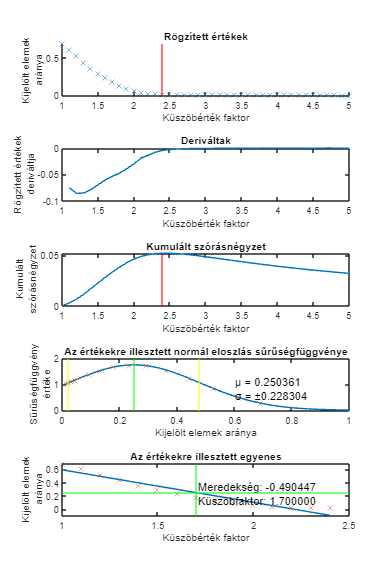

Value = {};
Metric = {};
Followflowfront = {};
Cutplacename = {};
Idthresh = [];
Slope = [];
Sigma = [];
Frac = [];
figlist = {};

% Shearrates
[highsheardiffs_r, normalsheardiffs_r, highsheardiffsbytimestep_r, ideal_threshold_shear_r, slope_shear_r, s_shear_r, frac_shear_r, ctpn_shear_r, fig_shear_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, sheardiffs_r, false, true, 0.1, 10);

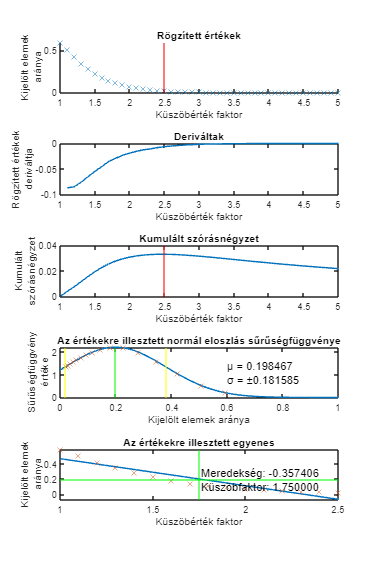

Value{1} = 'shearrate';
Metric{1} = 'max-min';
Followflowfront{1} = 'no';
Cutplacename{1} = ctpn_shear_r;
Idthresh(1) = ideal_threshold_shear_r;
Slope(1) = slope_shear_r;
Sigma(1) = s_shear_r;
Frac(1) = frac_shear_r;
figlist{1} = fig_shear_r;

[highsheardiffs_n, normalsheardiffs_n, highsheardiffsbytimestep_n, ideal_threshold_shear_n, slope_shear_n, s_shear_n, frac_shear_n, ctpn_shear_n, fig_shear_n] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, sheardiffs_n, false, true, 0.1, 10);

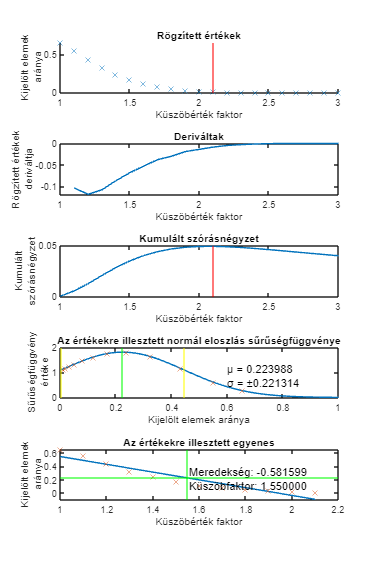

Value{2} = 'shearrate';
Metric{2} = '(max-min)/mean';
Followflowfront{2} = 'no';
Cutplacename{2} = ctpn_shear_n;
Idthresh(2) = ideal_threshold_shear_n;
Slope(2) = slope_shear_n;
Sigma(2) = s_shear_n;
Frac(2) = frac_shear_n;
figlist{2} = fig_shear_n;

[highsheardiffs_rr, normalsheardiffs_rr, highsheardiffsbytimestep_rr, ideal_threshold_shear_rr, slope_shear_rr, s_shear_rr, frac_shear_rr, ctpn_shear_rr, fig_shear_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, sheardiffs_rr, false, true, 0.1, 10);

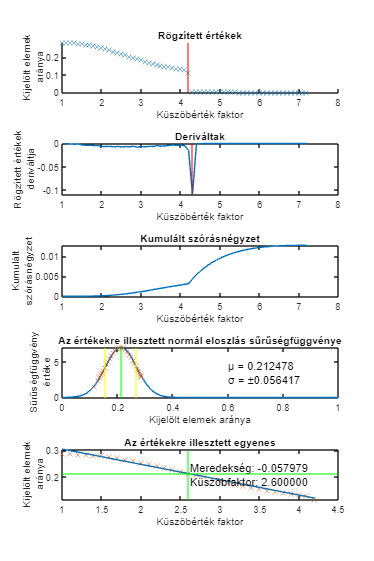

Value{3} = 'shearrate';
Metric{3} = '(max-min)/max';
Followflowfront{3} = 'no';
Cutplacename{3} = ctpn_shear_rr;
Idthresh(3) = ideal_threshold_shear_rr;
Slope(3) = slope_shear_rr;
Sigma(3) = s_shear_rr;
Frac(3) = frac_shear_rr;
figlist{3} = fig_shear_rr;

% Temperatures
[hightempdiffs_r, normaltempdiffs_r, hightempdiffsbytimestep_r, ideal_threshold_temp_r, slope_temp_r, s_temp_r, frac_temp_r, ctpn_temp_r, fig_temp_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, tempdiffs_r, true, true, 0.1, 10);

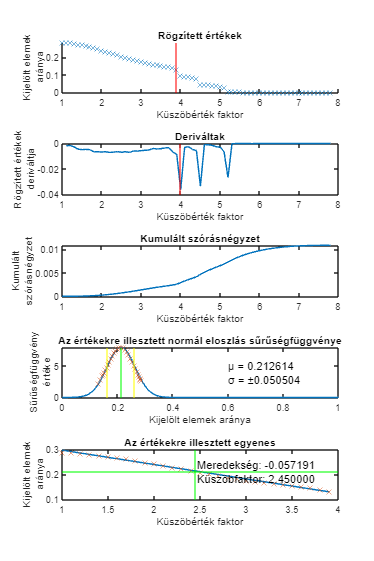

Value{4} = 'temperature';
Metric{4} = 'max-min';
Followflowfront{4} = 'yes';
Cutplacename{4} = ctpn_temp_r;
Idthresh(4) = ideal_threshold_temp_r;
Slope(4) = slope_temp_r;
Sigma(4) = s_temp_r;
Frac(4) = frac_temp_r;
figlist{4} = fig_temp_r;

[hightempdiffs_n, normaltempdiffs_n, hightempdiffsbytimestep_n, ideal_threshold_temp_n, slope_temp_n, s_temp_n, frac_temp_n, ctpn_temp_n, fig_temp_n] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, tempdiffs_n, true, true, 0.1, 10);

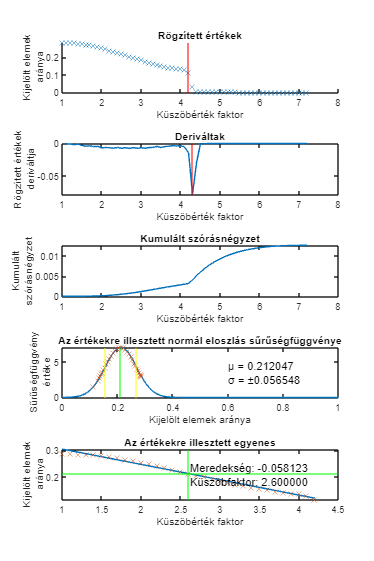

Value{5} = 'temperature';
Metric{5} = '(max-min)/mean';
Followflowfront{5} = 'yes';
Cutplacename{5} = ctpn_temp_n;
Idthresh(5) = ideal_threshold_temp_n;
Slope(5) = slope_temp_n;
Sigma(5) = s_temp_n;
Frac(5) = frac_temp_n;
figlist{5} = fig_temp_n;

[hightempdiffs_rr, normaltempdiffs_rr, hightempdiffsbytimestep_rr, ideal_threshold_temp_rr, slope_temp_rr, s_temp_rr, frac_temp_rr, ctpn_temp_rr, fig_temp_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, tempdiffs_rr, true, true, 0.1, 10);

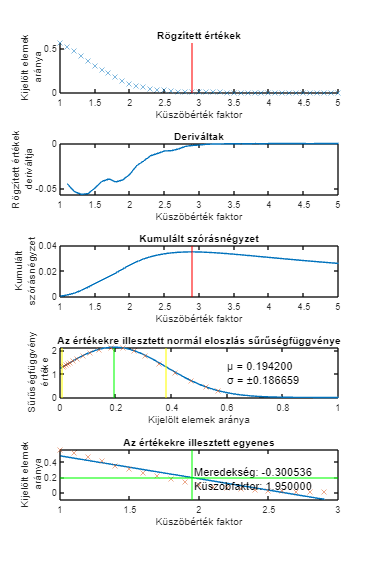

Value{6} = 'temperature';
Metric{6} = '(max-min)/max';
Followflowfront{6} = 'yes';
Cutplacename{6} = ctpn_temp_rr;
Idthresh(6) = ideal_threshold_temp_rr;
Slope(6) = slope_temp_rr;
Sigma(6) = s_temp_rr;
Frac(6) = frac_temp_rr;
figlist{6} = fig_temp_rr;

% Velocity vector lengths
[highvellendiffs_r, normalvellendiffs_r, highvellendiffsbytimestep_r, ideal_threshold_vellen_r, slope_vellen_r, s_vellen_r, frac_vellen_r, ctpn_vellen_r, fig_vellen_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, vellendiffs_r, false, true, 0.1, 10);

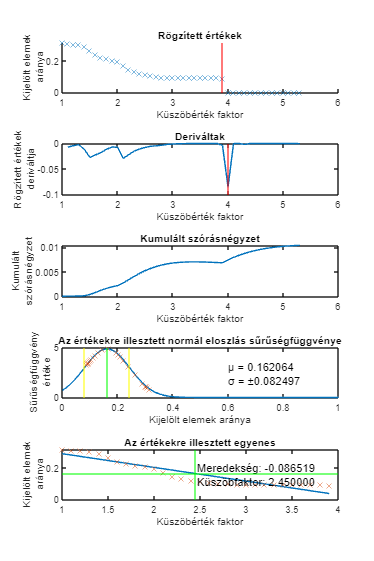

Value{7} = 'length of velocity vector';
Metric{7} = 'max-min';
Followflowfront{7} = 'no';
Cutplacename{7} = ctpn_vellen_r;
Idthresh(7) = ideal_threshold_vellen_r;
Slope(7) = slope_vellen_r;
Sigma(7) = s_vellen_r;
Frac(7) = frac_vellen_r;
figlist{7} = fig_vellen_r;

[highvellendiffs_n, normalvellendiffs_n, highvellendiffsbytimestep_n, ideal_threshold_vellen_n, slope_vellen_n, s_vellen_n, frac_vellen_n, ctpn_vellen_n, fig_vellen_n] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, vellendiffs_n, false, true, 0.1, 10);

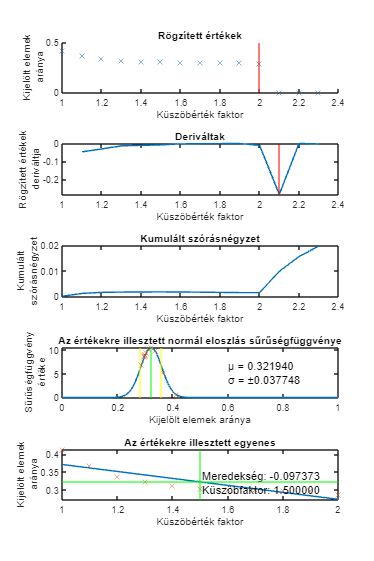

Value{8} = 'length of velocity vector';
Metric{8} = '(max-min)/mean';
Followflowfront{8} = 'no';
Cutplacename{8} = ctpn_vellen_n;
Idthresh(8) = ideal_threshold_vellen_n;
Slope(8) = slope_vellen_n;
Sigma(8) = s_vellen_n;
Frac(8) = frac_vellen_n;
figlist{8} = fig_vellen_n;

[highvellendiffs_rr, normalvellendiffs_rr, highvellendiffsbytimestep_rr, ideal_threshold_vellen_rr, slope_vellen_rr, s_vellen_rr, frac_vellen_rr, ctpn_vellen_rr, fig_vellen_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, vellendiffs_rr, false, true, 0.1, 10);

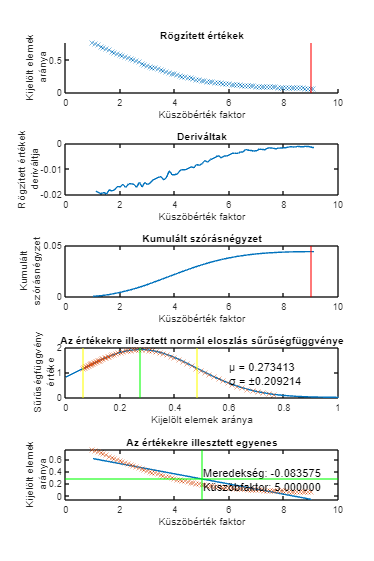

Value{9} = 'length of velocity vector';
Metric{9} = '(max-min)/max';
Followflowfront{9} = 'no';
Cutplacename{9} = ctpn_vellen_rr;
Idthresh(9) = ideal_threshold_vellen_rr;
Slope(9) = slope_vellen_rr;
Sigma(9) = s_vellen_rr;
Frac(9) = frac_vellen_rr;
figlist{9} = fig_vellen_rr;

% Velocity vector angles
[highanglediffs_r, normalanglediffs_r, highanglediffsbytimestep_r, ideal_threshold_angle_r, slope_angle_r, s_angle_r, frac_angle_r, ctpn_angle_r, fig_angle_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, anglediffs_r, false, true, 0.1, 10);

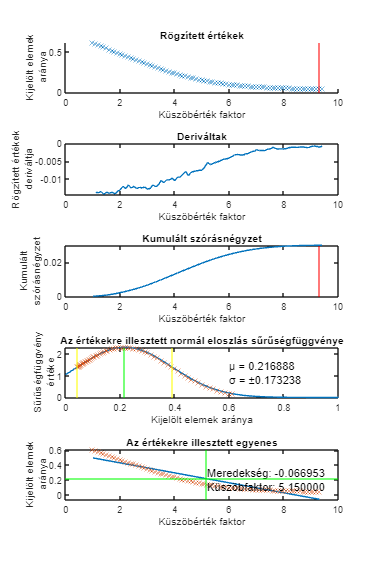

Value{10} = 'angle of velocity vector';
Metric{10} = 'max-min';
Followflowfront{10} = 'no';
Cutplacename{10} = ctpn_angle_r;
Idthresh(10) = ideal_threshold_angle_r;
Slope(10) = slope_angle_r;
Sigma(10) = s_angle_r;
Frac(10) = frac_angle_r;
figlist{10} = fig_angle_r;

[highanglediffs_n, normalanglediffs_n, highanglediffsbytimestep_n, ideal_threshold_angle_n, slope_angle_n, s_angle_n, frac_angle_n, ctpn_angle_n, fig_angle_n] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, anglediffs_n, false, true, 0.1, 10);

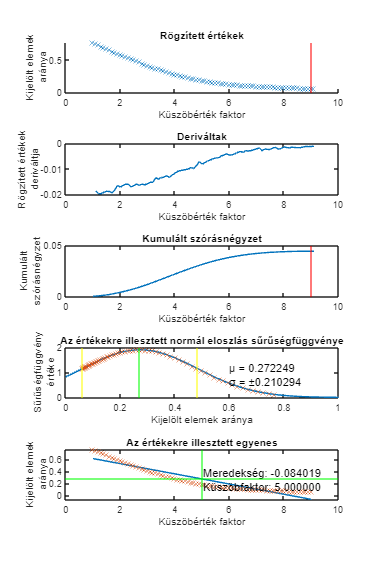

Value{11} = 'angle of velocity vector';
Metric{11} = '(max-min)/mean';
Followflowfront{11} = 'no';
Cutplacename{11} = ctpn_angle_n;
Idthresh(11) = ideal_threshold_angle_n;
Slope(11) = slope_angle_n;
Sigma(11) = s_angle_n;
Frac(11) = frac_angle_n;
figlist{11} = fig_angle_n;

[highanglediffs_rr, normalanglediffs_rr, highanglediffsbytimestep_rr, ideal_threshold_angle_rr, slope_angle_rr, s_angle_rr, frac_angle_rr, ctpn_angle_rr, fig_angle_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, anglediffs_rr, false, true, 0.1, 10);

Value{12} = 'angle of velocity vector';
Metric{12} = '(max-min)/max';
Followflowfront{12} = 'no';
Cutplacename{12} = ctpn_angle_rr;
Idthresh(12) = ideal_threshold_angle_rr;
Slope(12) = slope_angle_rr;
Sigma(12) = s_angle_rr;
Frac(12) = frac_angle_rr;
figlist{12} = fig_angle_rr;

logdata = table(Value', Metric', Followflowfront', Cutplacename', Idthresh', Slope', Sigma', Frac');

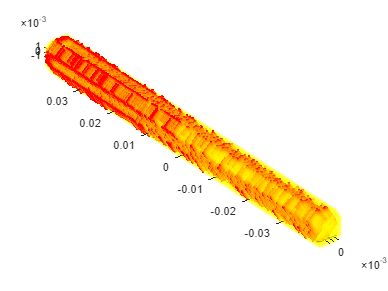

% Plotting elements to refine
elemfiglist = {};

elemfig_shear_r = easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_r, normalsheardiffs_r, 0);

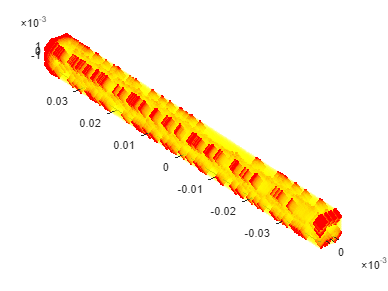

elemfiglist{1} = elemfig_shear_r;
elemfig_shear_n = easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_n, normalsheardiffs_n, 0);

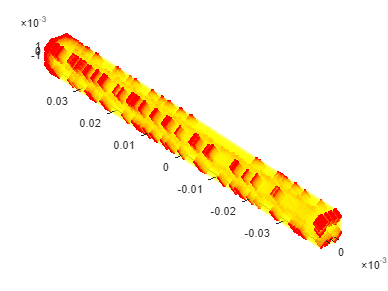

elemfiglist{2} = elemfig_shear_n;
elemfig_shear_rr = easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_rr, normalsheardiffs_rr, 0);

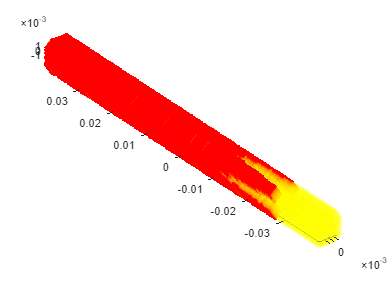

elemfiglist{3} = elemfig_shear_rr;

elemfig_temp_r = easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_r, normaltempdiffs_r, 0);

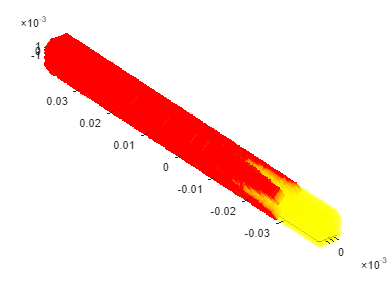

elemfiglist{4} = elemfig_temp_r;
elemefig_temp_n = easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_n, normaltempdiffs_n, 0);

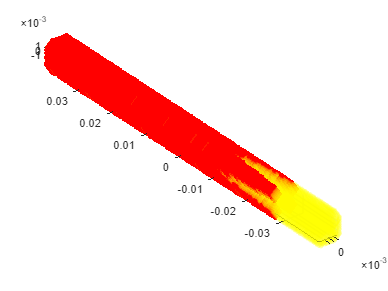

elemfiglist{5} = elemefig_temp_n;
elemfig_temp_rr = easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_rr, normaltempdiffs_rr, 0);

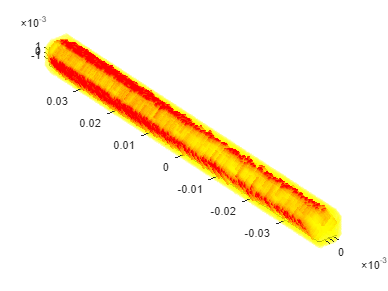

elemfiglist{6} = elemfig_temp_rr;

elemfig_vellen_r = easyvisualizer.plotElementsToRefine(elementcoordinates, highvellendiffs_r, normalvellendiffs_r, 0);

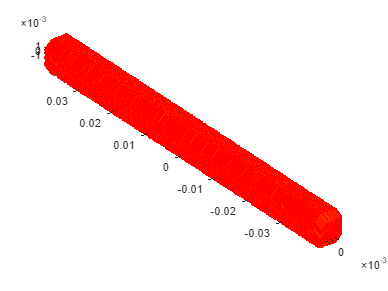

elemfiglist{7} = elemfig_vellen_r;
elemfig_vellen_n = easyvisualizer.plotElementsToRefine(elementcoordinates, highvellendiffs_n, normalvellendiffs_n, 0);

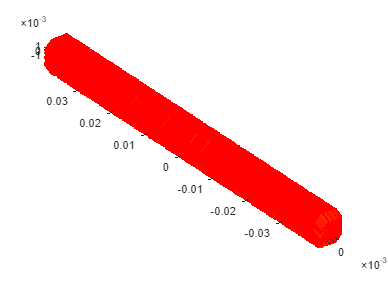

elemfiglist{8} = elemfig_vellen_n;
elemfig_vellen_rr = easyvisualizer.plotElementsToRefine(elementcoordinates, highvellendiffs_rr, normalvellendiffs_rr, 0);

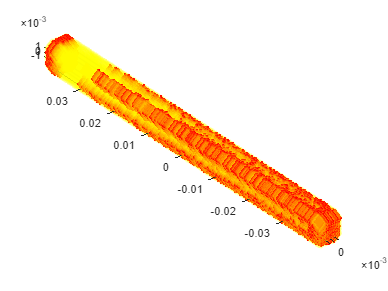

elemfiglist{9} = elemfig_vellen_rr;

elemfig_angle_r = easyvisualizer.plotElementsToRefine(elementcoordinates, highanglediffs_r, normalanglediffs_r, 0);

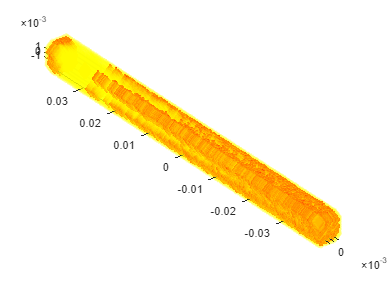

elemfiglist{10} = elemfig_angle_r;
elemfig_angle_n = easyvisualizer.plotElementsToRefine(elementcoordinates, highanglediffs_n, normalanglediffs_n, 0);

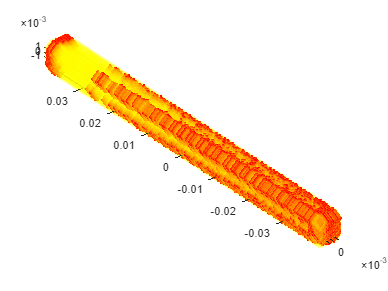

elemfiglist{11} = elemfig_angle_n;
elemfig_angle_rr = easyvisualizer.plotElementsToRefine(elementcoordinates, highanglediffs_rr, normalanglediffs_rr, 0);

elemfiglist{12} = elemfig_angle_rr;

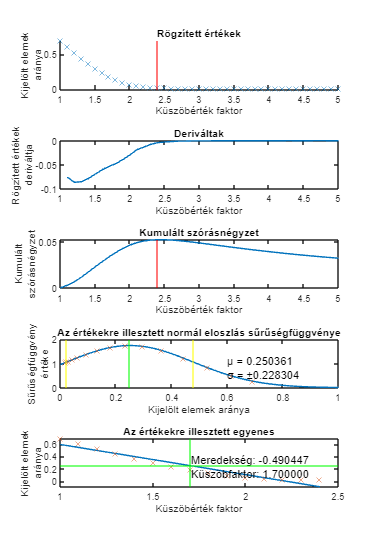

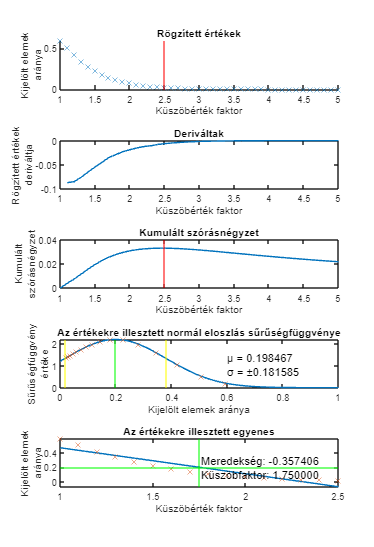

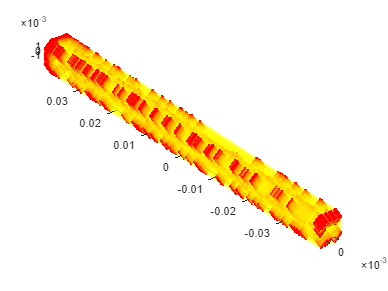

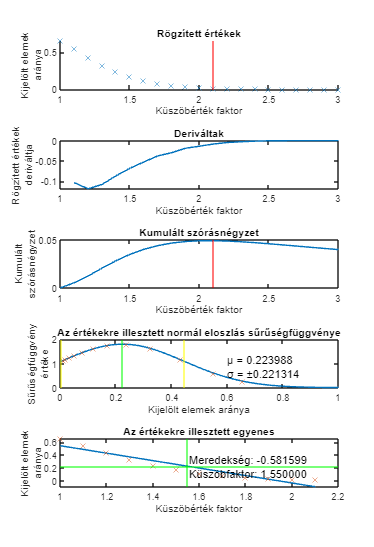

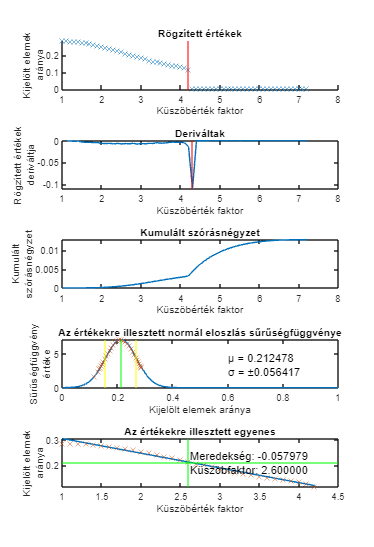

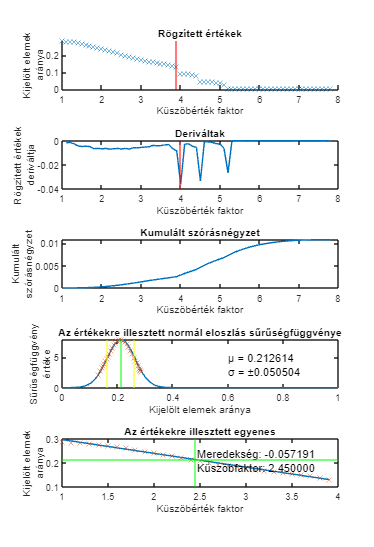

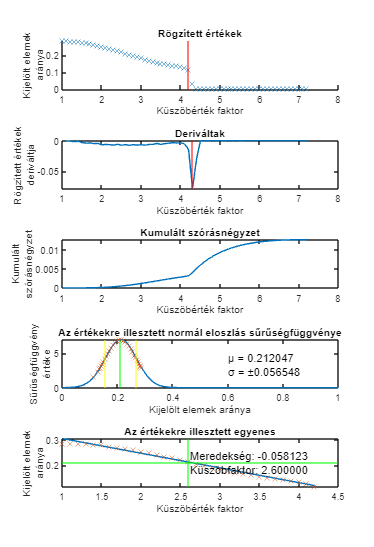

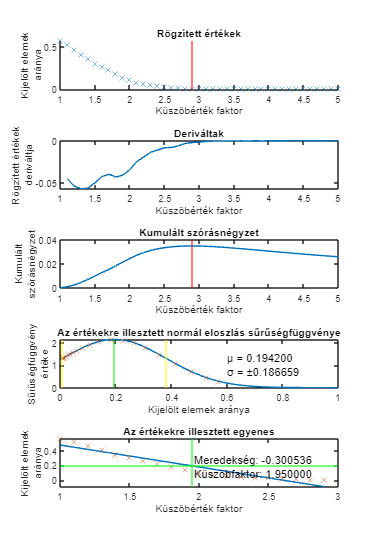


% Saving figures and logs
directory = {'shear', 'shear', 'shear', 'temp', 'temp', 'temp', 'vellen', 'vellen', 'vellen', 'angle', 'angle', 'angle'};
fignames = {'shear_r.png', 'shear_n.png', 'shear_rr.png' 'temp_r.png', 'temp_n.png', 'temp_rr.png', 'vellen_r.png', 'vellen_n.png', 'vellen_rr.png', 'angle_r.png', 'angle_n.png', 'angle_rr.png'};
elemfignames = {'elem_shear_r.png', 'elem_shear_n.png', 'elem_shear_rr.png' 'elem_temp_r.png', 'elem_temp_n.png', 'elem_temp_rr.png', 'elem_vellen_r.png', 'elem_vellen_n.png', 'elem_vellen_rr.png', 'elem_angle_r.png', 'elem_angle_n.png', 'elem_angle_rr.png'};

if savestuff
    for i=1:length(figlist)
         % Save the main figure
        print(figlist{i}, fullfile(logs_dir_name, directory{i}, fignames{i}), '-dpng');
        
        % Save the element figure
        print(elemfiglist{i}, fullfile(logs_dir_name, directory{i}, elemfignames{i}), '-dpng');
    end
end


writetable(logdata, fullfile(logs_dir_name, 'logs.csv'), 'Encoding', 'UTF-8');
